## Correlation Techniques for Facial Recognition

Correlation techniques are mainly used in optical systems, based on the 4f-correlator architecture. The main objective is to implement recognition by identifying the peaks in a cross-correlation function between a target image and a reference image. Those concepts are betterunderstood in the Fourier space. I proceed to introduce two fundamental concepts for image processing and how to play arround with them in MATLAB:

- Convolution of Images

- Crosscorrelation of Images

### Convolution of Images

The convolution of images is kind of an overlap between two functions in an n-dimensional space. Mathematically, it is defined by the equation:


$$f * h (\vec{x}) = \int_{-\infty}^{\infty} d\vec{u} f(\vec{u})h(\vec{x}-\vec{u})$$


For my first test, I will show the convolution between a lattice and a 2D image.

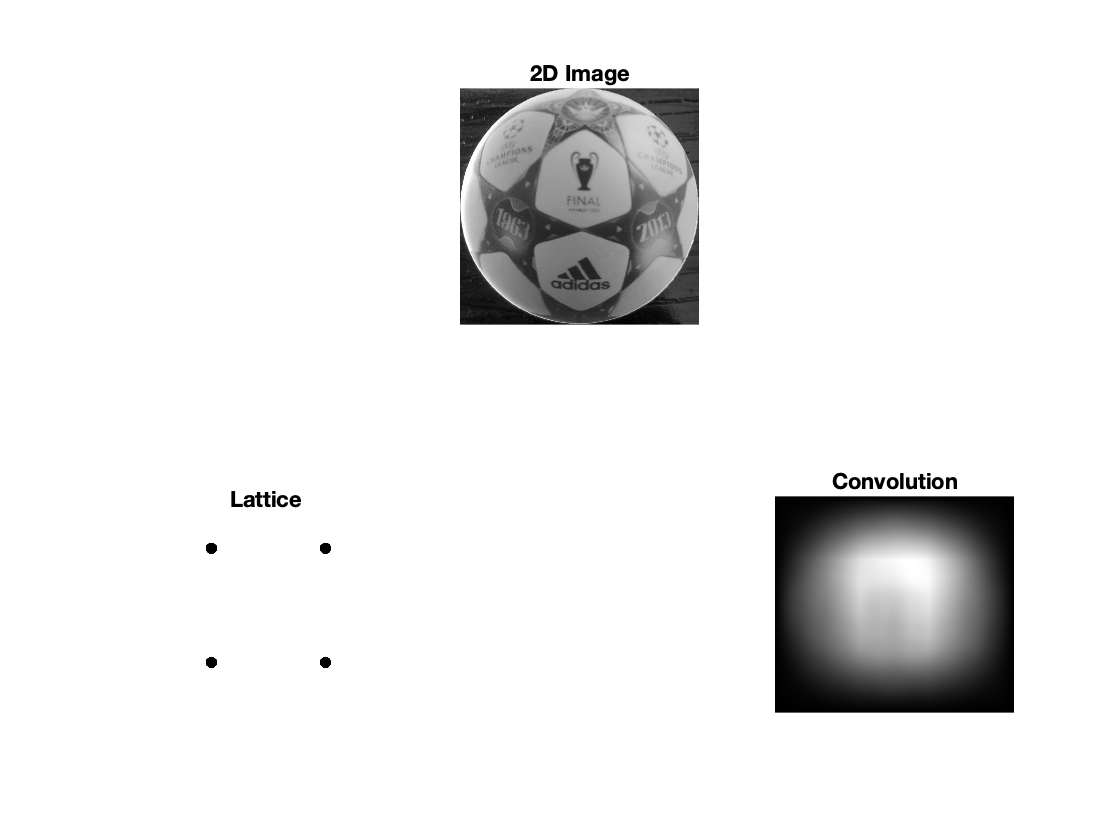

refsize = [680,680];
im1 = imread('test.png');       % gets 2D image for test
%im1 = imresize(im1,refsize);    % To avoid inconsistencies
im1 = rgb2gray(im1);            % Converts it into uint8 matrix
im1 = double(im1);              %   " it into double for conv.

im2 = imread('Lattice2.png');   % gets lattice for conv.
%im2 = imresize(im2,refsize);    % To avoid inconsistencies
im2 = rgb2gray(im2);            % Converts it into uint8 matrix
im2 = double(im2);              %   " it into double for conv.

myconv = conv2(im1,im2,'full');  % Computes full 2D convolution

subplot(2,3,2);
imshow(im1,[]);
title('2D Image');

subplot(2,3,4);
imshow(im2,[]);
title('Lattice');

subplot(2,3,6);
imshow(myconv,[]);
title('Convolution');

Now, I will show the convolution between a 2D Image and a High Pass Filter. I don't know how to this in space domain, but I will try to do it using the **convolution theorem**:


$$f * h = \mathcal{F}^{-1}[\mathcal{F}[f]\cdot\mathcal{F}[h]]$$


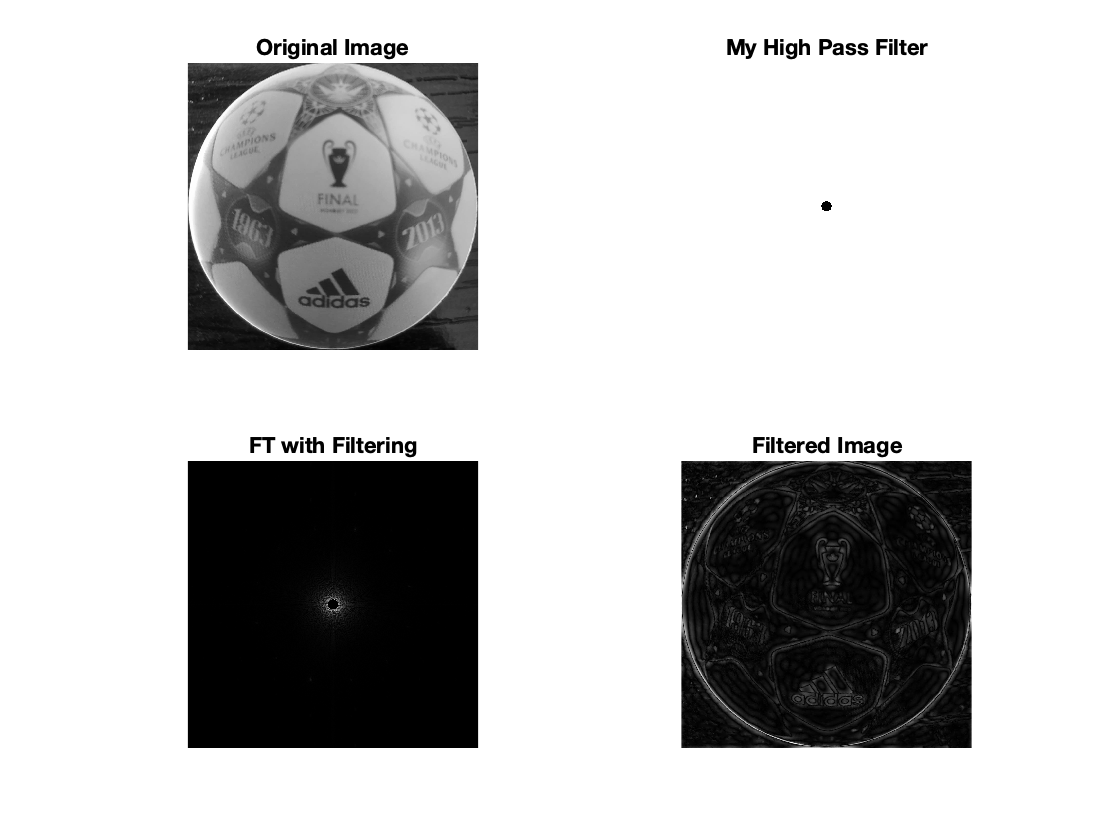

im1 = imread('test.png');
im1 = rgb2gray(im1);
fftim1 = fftshift(fft2(im1));
sizeim = size(fftim1);

% Parameters for the construction of the filter
radfilter = 20;                
partition = 500;
hpfilter = ones(sizeim);
xcenter = int16(sizeim(1)/2);
ycenter = int16(sizeim(2)/2);
% Construction of the filter
for i = 0:partition
    for j = 0:partition
        t = radfilter*((1.0*j)/partition)*cos(2*pi/partition*i)+xcenter;
        r = radfilter*((1.0*j)/partition)*sin(2*pi/partition*i)+ycenter;
        hpfilter(int16(t),int16(r)) = 0;
    end
end

% Product of filter and fft of image
fftim1filt = fftim1 .* hpfilter;

% Filtered Image
im1filt = ifft2(fftim1filt);

% Plotting results
subplot(2,2,1);
imshow(im1,[]);
title('Original Image');

hpfilter = immultiply(hpfilter,255);
subplot(2,2,2);
imshow(hpfilter,[]);
title('My High Pass Filter');

subplot(2,2,3)
imshow(abs(fftim1filt),[]);
title('FT with Filtering');

subplot(2,2,4);
imshow(abs(im1filt),[]);
title('Filtered Image');

Now, I will try to include the built-in camera to see if I can have a video with edge detection

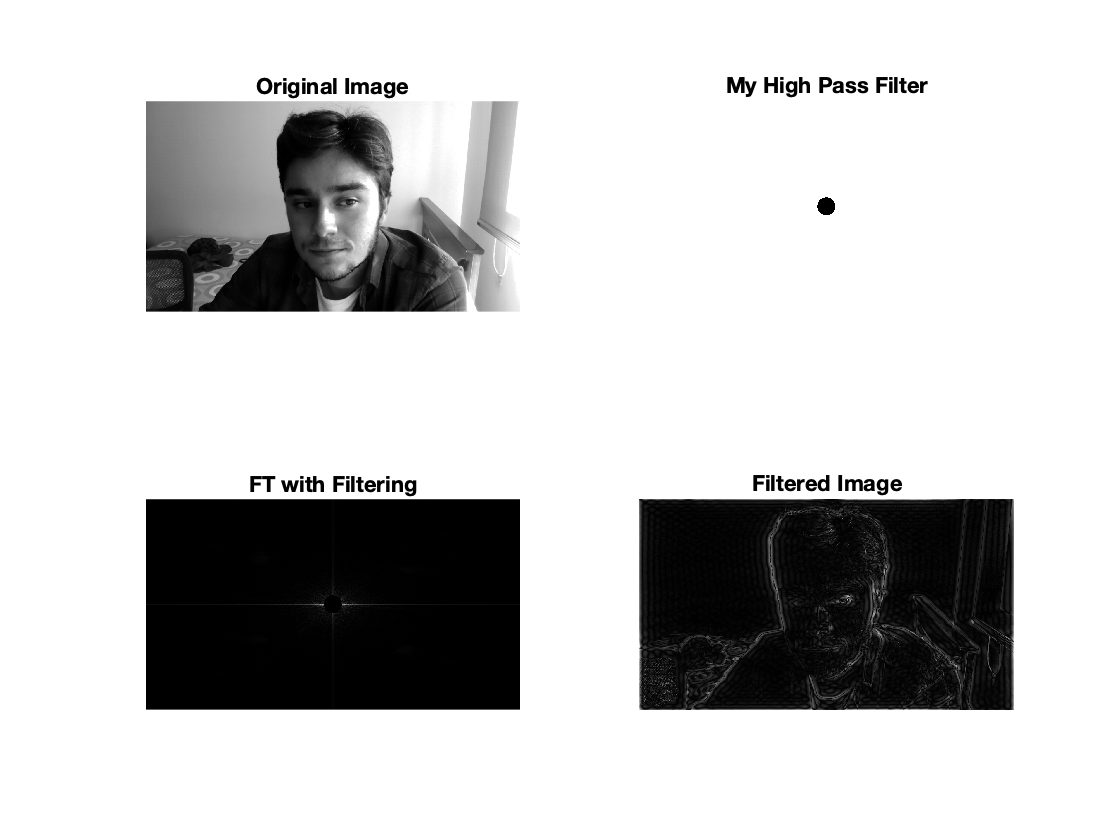

im1 = snapshot(cam);
im1 = rgb2gray(im1);
fftim1 = fftshift(fft2(im1));
sizeim = size(fftim1);

% Parameters for the construction of the filter
radfilter = 30;                
partition = 500;
hpfilter = ones(sizeim);
xcenter = int16(sizeim(1)/2);
ycenter = int16(sizeim(2)/2);
% Construction of the filter
for i = 0:partition
    for j = 0:partition
        t = radfilter*((1.0*j)/partition)*cos(2*pi/partition*i)+xcenter;
        r = radfilter*((1.0*j)/partition)*sin(2*pi/partition*i)+ycenter;
        hpfilter(int16(t),int16(r)) = 0;
    end
end

% Product of filter and fft of image
fftim1filt = fftim1 .* hpfilter;

% Filtered Image
im1filt = ifft2(fftim1filt);

% Plotting results
subplot(2,2,1);
imshow(im1,[]);
title('Original Image');

hpfilter = immultiply(hpfilter,255);
subplot(2,2,2);
imshow(hpfilter,[]);
title('My High Pass Filter');

subplot(2,2,3)
imshow(abs(fftim1filt),[]);
title('FT with Filtering');

subplot(2,2,4);
imshow(abs(im1filt),[]);
title('Filtered Image');

Now, I can implement the computation of correlation using the FFT:


$$f\otimes h = \mathcal{F}^{-1}[\mathcal{F}[f]^{*} \cdot \mathcal{F}[h]]$$


Correlation is defined by the equation:


$$f \otimes h = \int_{-\infty}^{\infty} d\vec{u} f(\vec{u}) g(\vec{x}+\vec{u})$$


So, I decided to test the correlation of an image with itself.

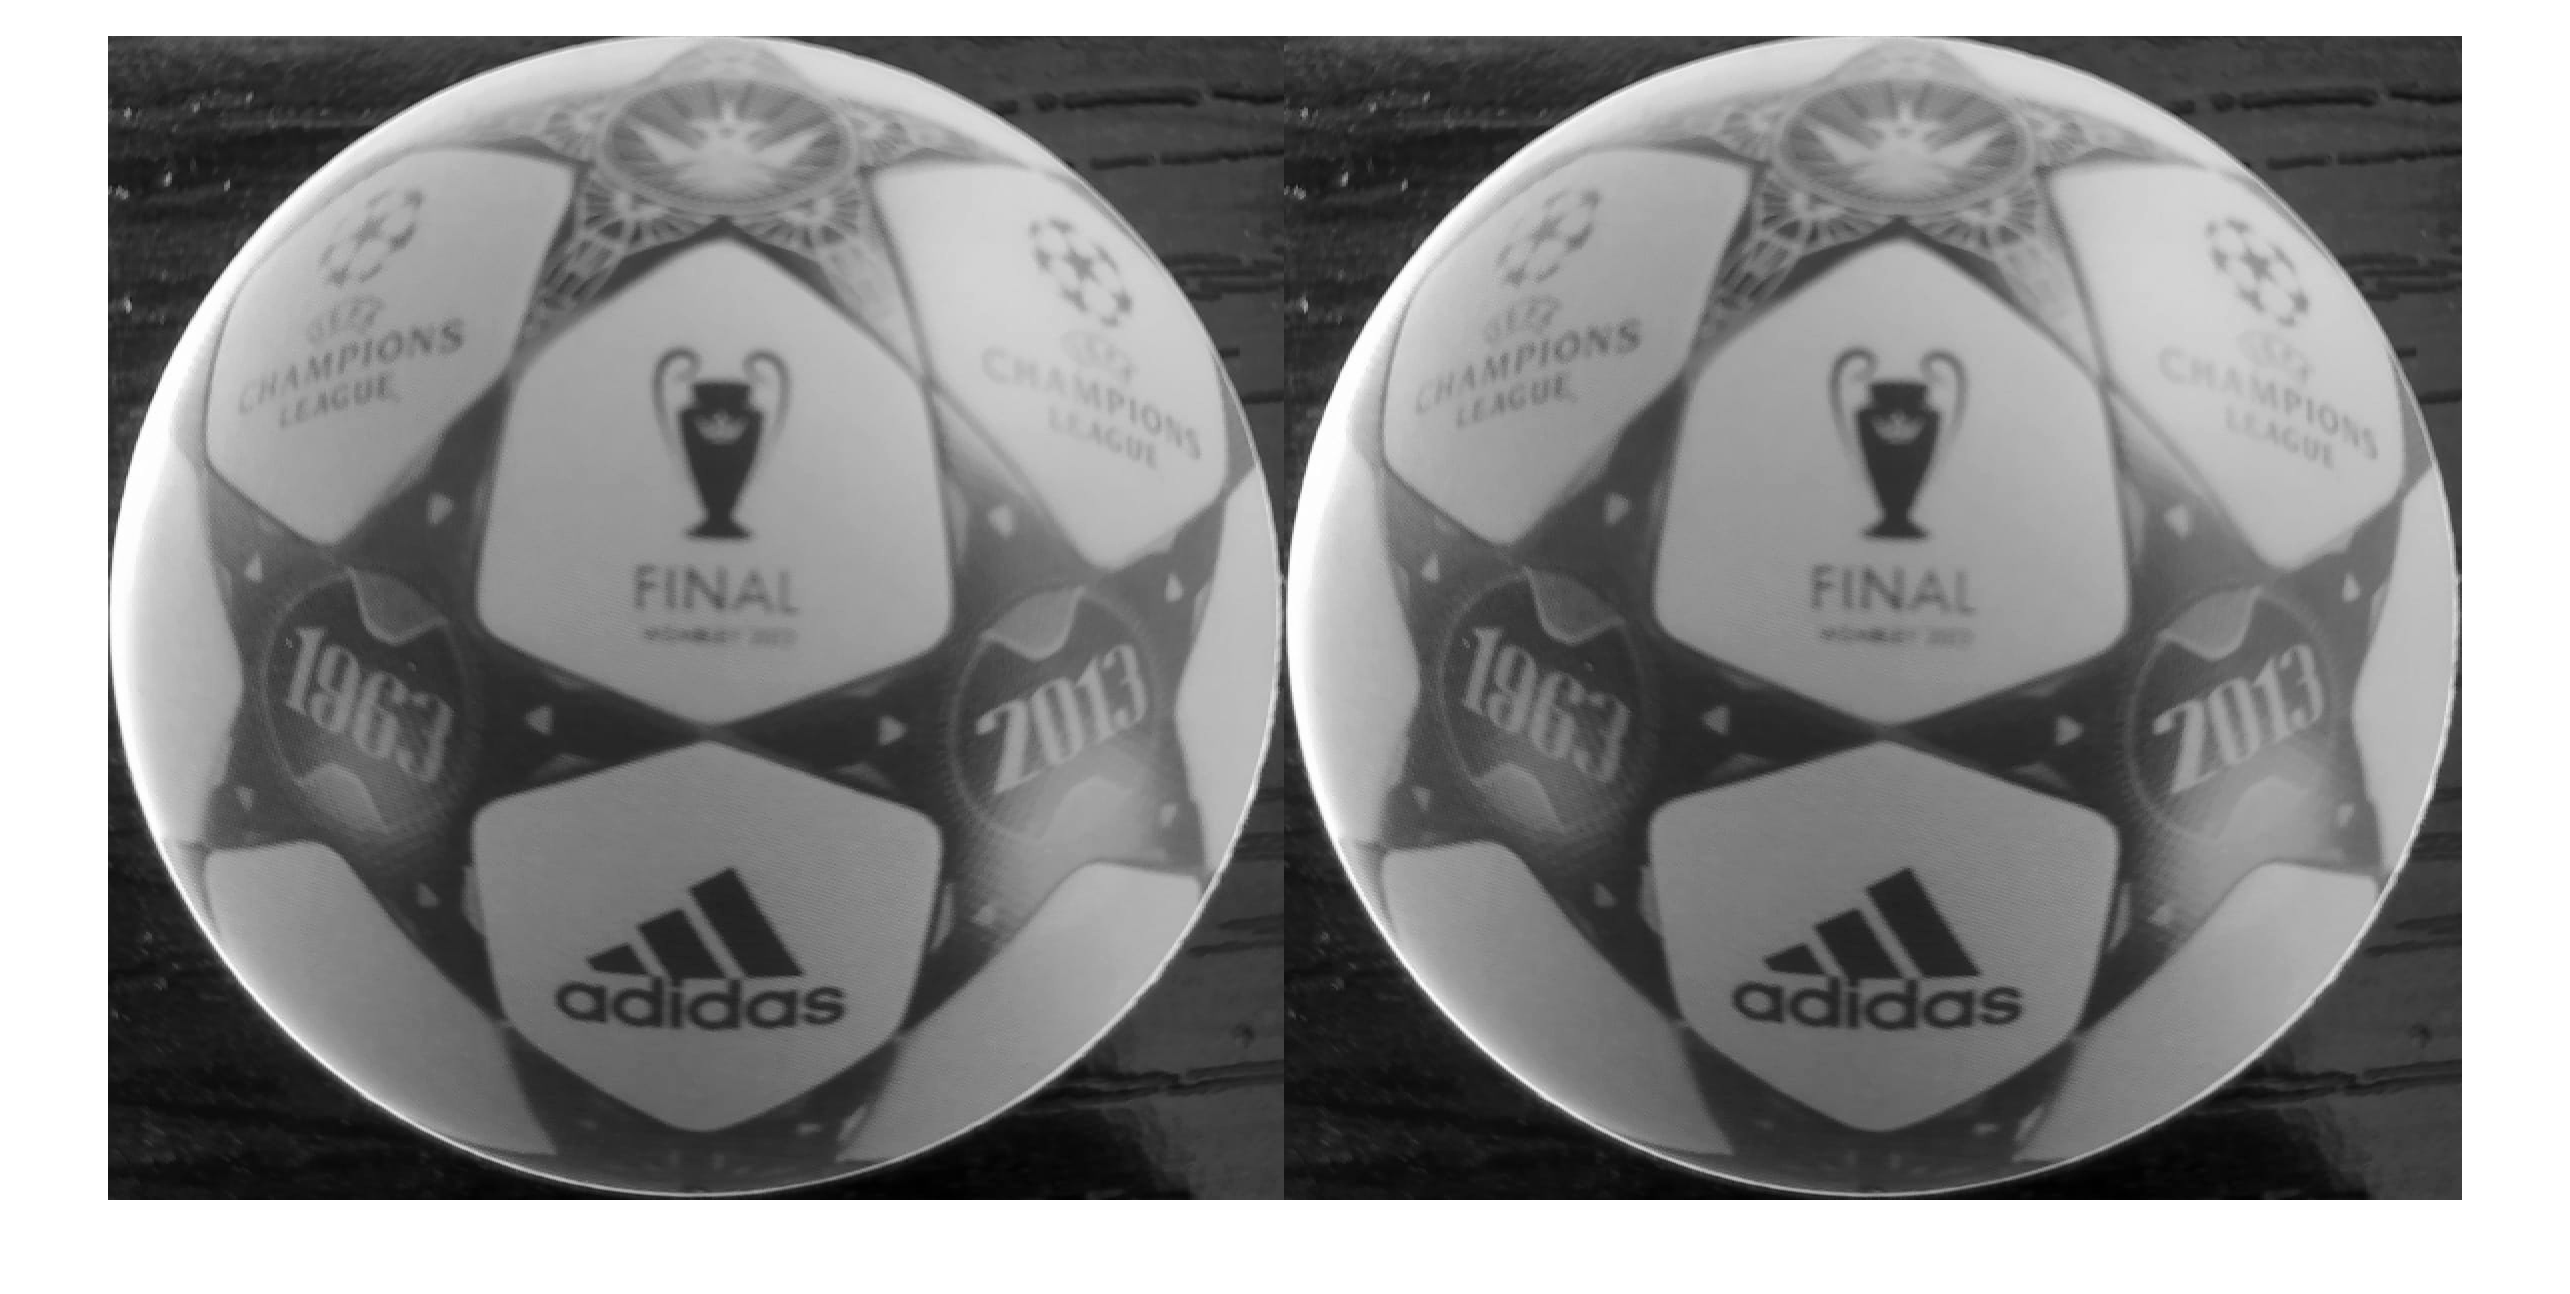

im1 = rgb2gray(imread('test.png'));
tic;
fftim1 = fftshift(fft2(im1));
fftim2 = conj(fftim1);
fftcor = fftim1 .* fftim2;
cor = fftshift(ifft2(fftcor));
t1 = toc;
imshowpair(im1,im1,'montage');

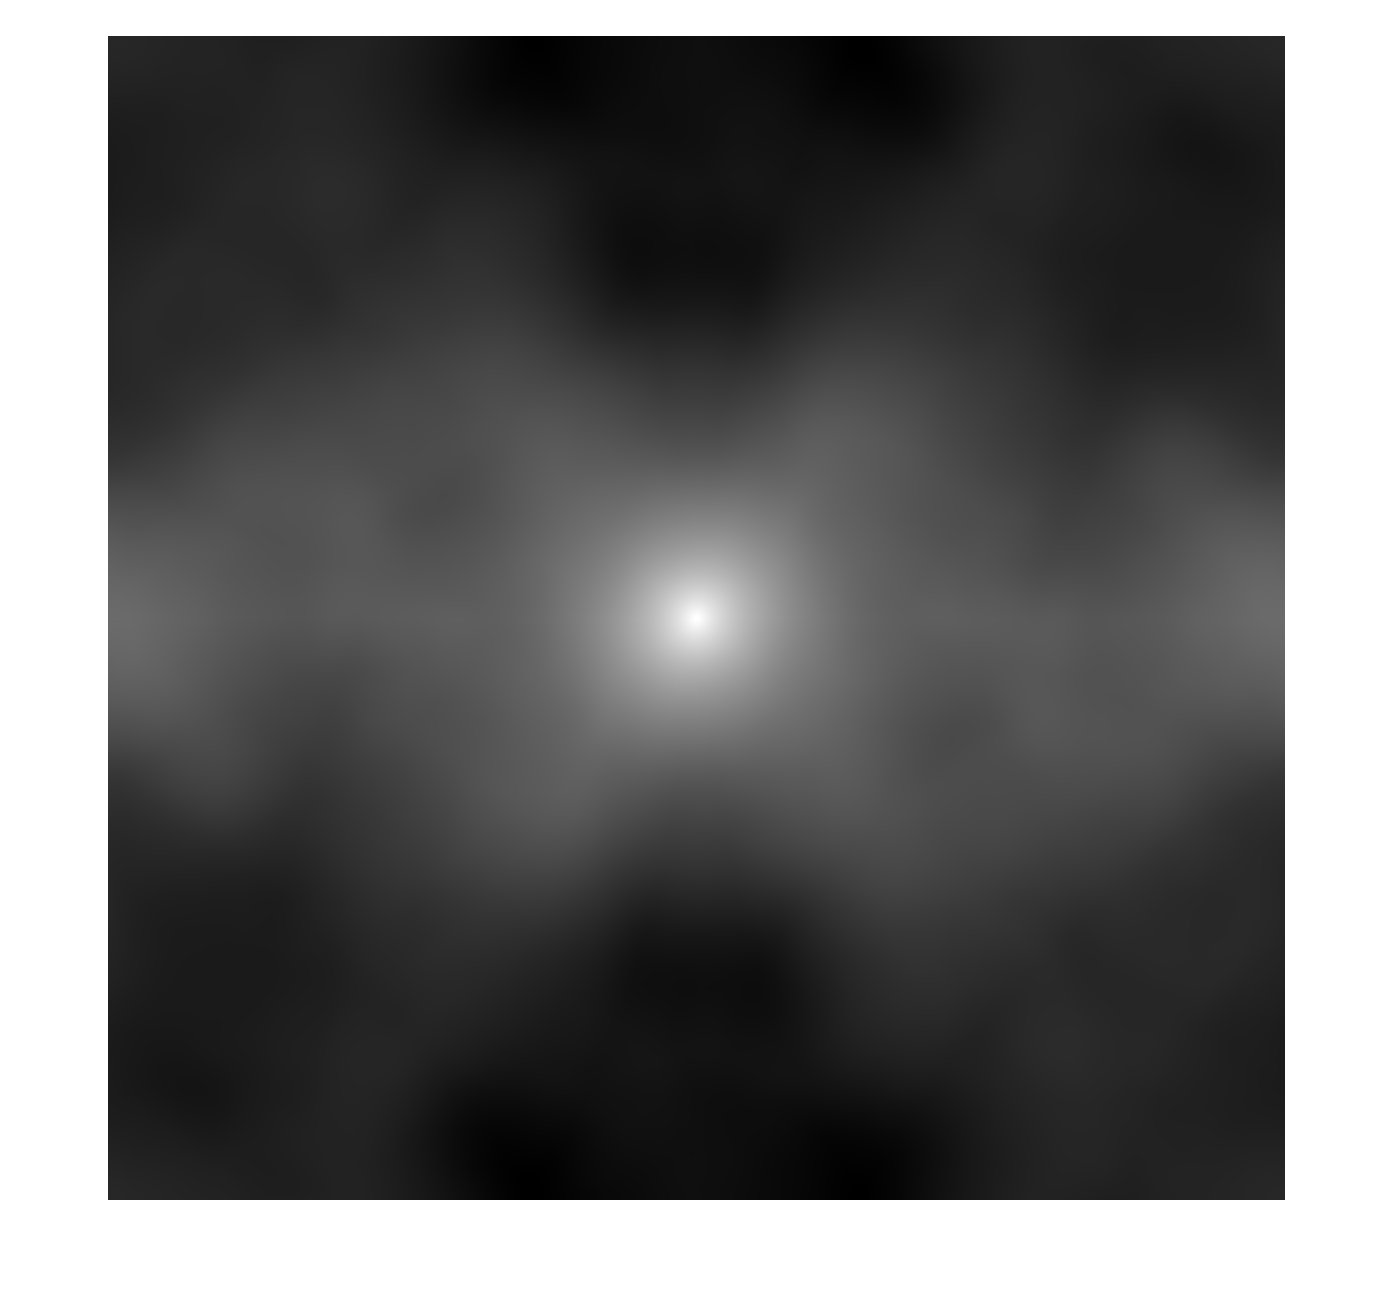

imshow(abs(cor),[]);

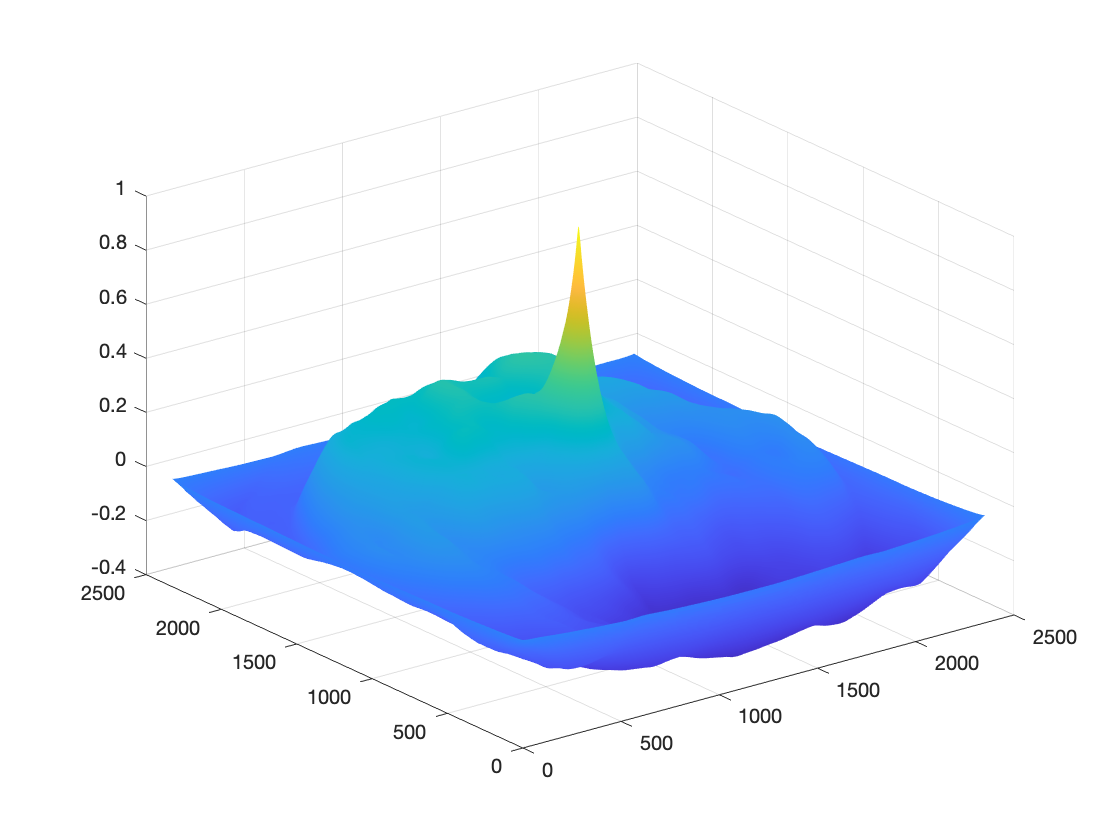

[xpeak1, ypeak1] = find(cor == max(cor(:)));

t2 = toc;
c = normxcorr2(im1,im1);
t3 = toc;
[xpeak2, ypeak2] = find(c == max(c(:)));
figure, surf(c), shading flat